side 4 heat Eq

page 16

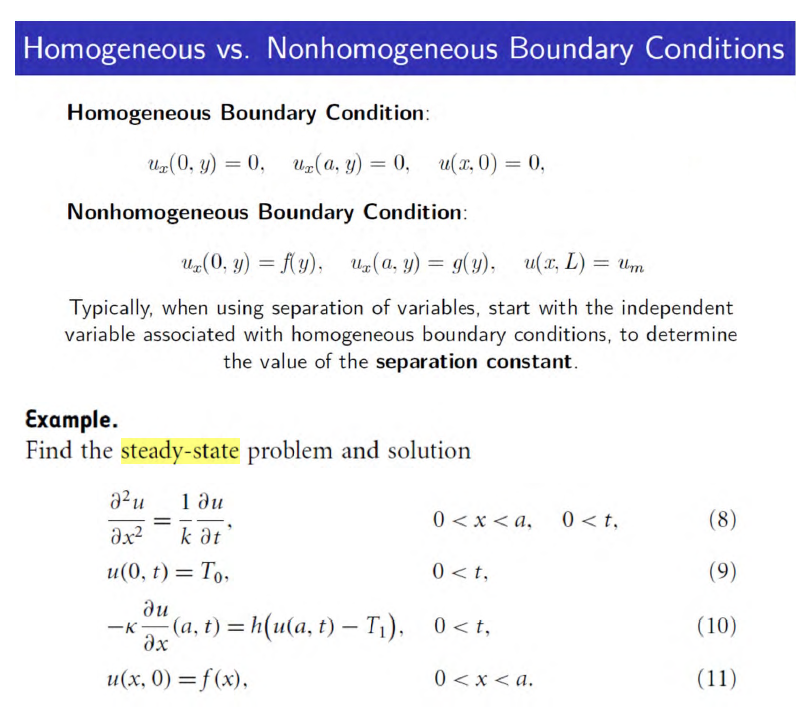

clear
clf
clc
syms x t u(x,t) a
syms k a T0 T1 h fx
assume(x,"positive")
assume(t,"positive")
Eq = diff(u,x,2) == (1/k)*diff(u,t);
con1 = u(0,t) == T0;
con2 =  -k*diff(u(a,t),t) == h*(u(a,t)-T1);
con3 =  u(x,0) == fx;

u(x,t)    is the temperature distribution in a one-dimensional rod

k          is the thermal conductivity

h          is the heat transfer coefficient

T0,T1   are temperatures

a          is  the length of the rod

f(x)       is the initial temperature distribution along the rod.

at steady-state แปลว่า จะคงที่ไม่มีการเปลี่ยนแปลงไปกับเวลาดังนั้นจะได้ว่า

conS1 = diff(u,t) == 0; %steady state condition 
conS2= subs(Eq,diff(u,t),0)%จาก conS1

$$conS2(x, t) = \frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)=0$$

แสดงว่า u(x,t) นั้นเป็นสมการที่ไม่ขึ้นกับเวลา

ทำให้ได้ condition ใหม่เป็น

syms v(x) A B
con1 = v(0) == T0

$$con1 = v\left(0\right)=T_{0}$$

con2 = -k*diff(v(a)) == h*(v(a)-T1)

$$con2 = -k\,\frac{\partial }{\partial a}v\left(a\right)=-h\,\left(T_{1}-v\left(a\right)\right)$$

และจาก conS2 แสดงว่า

v(x) = A*x + B

$$v(x) = B+A\,x$$

จาก con1

Eq2 = T0 == subs(v,x,0) % ตาม con1

$$Eq2(x) = T_{0}=B$$

B = solve(Eq2,B)%จัดรูปใน term B

$$B = T_{0}$$

v = subs(v) % แทน B ด้วย T0

$$v(x) = T_{0}+A\,x$$

Eq3 = subs(con2)% แทน v(a) ด้วย v(x)

$$Eq3 = -A\,k=h\,\left(T_{0}-T_{1}+A\,a\right)$$

A = solve(Eq3,A)% จัดรูปใน terem A

$$A = -\frac{h\,\left(T_{0}-T_{1}\right)}{k+a\,h}$$

v = subs(v)% เอา A และ B แทนใน v(x) = Ax +B

$$v(x) = T_{0}-\frac{h\,x\,\left(T_{0}-T_{1}\right)}{k+a\,h}$$

page 26

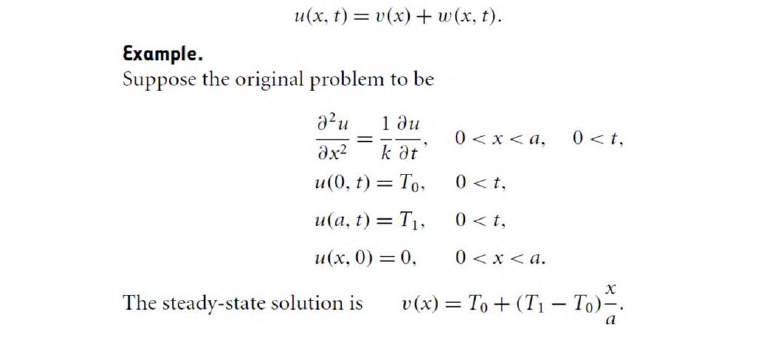

clear
clf
clc 
syms u(x,t) x t a
syms T0 T1 k
assume(x,'positive')
assume(a,'positive')
Eq = diff(u,x,2) == (1/k)*diff(u,t)

$$Eq(x, t) = \frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)=\frac{\frac{\partial }{\partial t}u\left(x,t\right)}{k}$$

con1 = u(0,t) == T0

$$con1 = u\left(0,t\right)=T_{0}$$

con2 = u(a,t) == T1

$$con2 = u\left(a,t\right)=T_{1}$$

con3 = u(x,0) == 0

$$con3 = u\left(x,0\right)=0$$

find The steady-state solution

condition for steady state is

conSS = diff(u,t) == 0; 

จาก conS1 เมื่อนำไปแทนใน Eq จะได้ว่า 

subs(Eq,diff(u,t),0)

$$ans(x, t) = \frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)=0$$

เมื่อ diff(x) 2 รอบ แล้วได้เท่ากับ 0 แสดงว่า steady state Eq เป็น

syms v(x) A B
v(x) = A*x + B % v(x) คือ u(x) ที่เป็น stesdy=state, ซึ่ง v(x) เป็นส่วนหนึ่งของ u(x) เราแค่ไปหา transient มาเพิ่มก็จะได้ u(x) ทั้งหมดที่ควรเป็น

$$v(x) = B+A\,x$$

จาก conSS จะได้ conditon ใหม่เป็น 

conS1 = v(0) == T0

$$conS1 = B=T_{0}$$

conS2 = v(a) == T1

$$conS2 = B+A\,a=T_{1}$$

% ส่วน con3 เหมือนเดิมเพราะอ้างอิงเวลาที่ t=0 ไว้แล้ว

แทน 0 ลงใน v(x) และนำไปเทียบกับ conS1

B = solve(conS1,B)

$$B = T_{0}$$

v(x) = subs(v);

A = solve(conS2,A);
A = subs(A)

$$A = -\frac{T_{0}-T_{1}}{a}$$

v(x) = subs(v)

$$v(x) = T_{0}-\frac{x\,\left(T_{0}-T_{1}\right)}{a}$$

% จบ partแรก คือได้ v(x),steady state of u(x)

ให้ w(x,t) คือ transient 

กล่าวคือ u(x,t) = w(x,t) + v(x)

syms w(x,t) 
w(x,t) = u(x,t) - v(x)

$$w(x, t) = u\left(x,t\right)-T_{0}+\frac{x\,\left(T_{0}-T_{1}\right)}{a}$$

จะได้ function and condition เป็นดังนี้

EqW = diff(w,x,2) == (1/k)*diff(w,t)

$$EqW(x, t) = \frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)=\frac{\frac{\partial }{\partial t}u\left(x,t\right)}{k}$$


conW1 = w(0,t) == 0

$$conW1 = u\left(0,t\right)-T_{0}=0$$

conW2 = w(a,t) == 0

$$conW2 = u\left(a,t\right)-T_{1}=0$$

conW3 = w(x,0) 

$$conW3 = u\left(x,0\right)-T_{0}+\frac{x\,\left(T_{0}-T_{1}\right)}{a}$$

conW3 = (subs(conW3,u(x,0),0)) % from con3

$$conW3 = \frac{x\,\left(T_{0}-T_{1}\right)}{a}-T_{0}$$

แก้ปัญหาด้วย seperate variable

%{
syms X(x) T(t) D 
SepVar = subs(EqW,w(x,t),X(x)*T(t));

SepVar = SepVar/(D*X(x)*T(t));
var = children(SepVar);
syms lambda
assume(lambda,"positive")
eqT = var(1) == -lambda^2
eqX = var(2) == -lambda^2
symfun(eqT)
T(t,lambda) = dsolve(eqT)
X(x,lambda) = dsolve(eqX)
constantX = setdiff(symvar(X(x,lambda)),sym(['C',x,lambda]))
%X(x,lambda) = subs(-X(x,lambda),constantX(2))
syms A B 
expT(t,lambda) = subs(T(t,lambda),[lambda,sym('C1')],[lambda,sym('1')]);
sinX(x,lambda) = subs(X(x,lambda),[lambda,sym('C1'),sym('C2')],[lambda,A,-B]);
ustruct(x,t) = collect(sinX(x,lambda)*expT(t,lambda),["sin" "exp"]);
%}

ver2

clear
clf
clc
syms u(x,t) K T0 T1 a v(x) t w(x,t) lambda_n x b(n)
assume(t,"positive")
assume(a,"positive")
BC0 = u(0,t) == T0

$$BC0 = u\left(0,t\right)=T_{0}$$

BCa = u(a,t) == T1

$$BCa = u\left(a,t\right)=T_{1}$$

v(x) = T0 + (T1-T0)*(x/a)

$$v(x) = T_{0}-\frac{x\,\left(T_{0}-T_{1}\right)}{a}$$

i = 3

i = 3

w(x,t) = u(x,t) - v(x) 

$$w(x, t) = u\left(x,t\right)-T_{0}+\frac{x\,\left(T_{0}-T_{1}\right)}{a}$$

Wxt = subs(w(x,t),u(x,t),0)

$$Wxt = \frac{x\,\left(T_{0}-T_{1}\right)}{a}-T_{0}$$

W(x,t) = symsum(b(n)*sin(lambda_n*x)*exp(-(lambda_n^2)*K*t),n,1,inf)

$$W(x, t) = {\mathrm{e}}^{-K\,{\lambda_{n}}^{2}\,t}\,\sin\left(\lambda_{n}\,x\right)\,\left(\sum_{n=1}^{\infty }b\left(n\right)\right)$$

%W(x,t) = symsum(W(x,t),lambda_n,1,inf)
W(x,t) = subs(W(x,t),lambda_n,n*pi/a)

$$W(x, t) = {\mathrm{e}}^{-\frac{K\,n^{2}\,t\,\pi^{2}}{a^{2}}}\,\sin\left(\frac{\pi \,n\,x}{a}\right)\,\left(\sum_{n=1}^{\infty }b\left(n\right)\right)$$

W(x,t) = symsum(W(x,t),n,1,inf)

$$W(x, t) = \sum_{n=1}^{\infty }{\mathrm{e}}^{-\frac{K\,n^{2}\,t\,\pi^{2}}{a^{2}}}\,\sin\left(\frac{\pi \,n\,x}{a}\right)\,\left(\sum_{n=1}^{\infty }b\left(n\right)\right)$$

b_n = 2/a*int(Wxt*sin(lambda_n*x),0,a)

$$b\_n = -\frac{2\,\left(\frac{T_{0}\,\lambda_{n}-T_{1}\,\lambda_{n}\,\cos\left(a\,\lambda_{n}\right)}{{\lambda_{n}}^{2}}-\frac{T_{0}\,\sin\left(a\,\lambda_{n}\right)-T_{1}\,\sin\left(a\,\lambda_{n}\right)}{a\,{\lambda_{n}}^{2}}\right)}{a}$$

b_n = subs(b_n,lambda_n,n*pi/a)

$$b\_n = \frac{2\,\left(\frac{a\,\left(T_{0}\,\sin\left(\pi \,n\right)-T_{1}\,\sin\left(\pi \,n\right)\right)}{n^{2}\,\pi^{2}}-\frac{a^{2}\,\left(\frac{\pi \,T_{0}\,n}{a}-\frac{\pi \,T_{1}\,n\,\cos\left(\pi \,n\right)}{a}\right)}{n^{2}\,\pi^{2}}\right)}{a}$$

b_n = symsum(b_n,n,1,i)

$$b\_n = -\frac{2\,a\,\left(\frac{\pi \,T_{0}}{a}+\frac{\pi \,T_{1}}{a}\right)}{\pi^{2}}-\frac{a\,\left(\frac{2\,\pi \,T_{0}}{a}-\frac{2\,\pi \,T_{1}}{a}\right)}{2\,\pi^{2}}-\frac{2\,a\,\left(\frac{3\,\pi \,T_{0}}{a}+\frac{3\,\pi \,T_{1}}{a}\right)}{9\,\pi^{2}}$$

W(x,t) = symsum(b_n*sin(lambda_n*x)*exp(-(lambda_n^2)*K*t),n,1,i)

$$W(x, t) = -3\,{\mathrm{e}}^{-K\,{\lambda_{n}}^{2}\,t}\,\sin\left(\lambda_{n}\,x\right)\,\left(\frac{2\,a\,\left(\frac{\pi \,T_{0}}{a}+\frac{\pi \,T_{1}}{a}\right)}{\pi^{2}}+\frac{a\,\left(\frac{2\,\pi \,T_{0}}{a}-\frac{2\,\pi \,T_{1}}{a}\right)}{2\,\pi^{2}}+\frac{2\,a\,\left(\frac{3\,\pi \,T_{0}}{a}+\frac{3\,\pi \,T_{1}}{a}\right)}{9\,\pi^{2}}\right)$$

W(x,t) = subs(W(x,t),lambda_n,n*pi/a)

$$W(x, t) = -3\,{\mathrm{e}}^{-\frac{K\,n^{2}\,t\,\pi^{2}}{a^{2}}}\,\sin\left(\frac{\pi \,n\,x}{a}\right)\,\left(\frac{2\,a\,\left(\frac{\pi \,T_{0}}{a}+\frac{\pi \,T_{1}}{a}\right)}{\pi^{2}}+\frac{a\,\left(\frac{2\,\pi \,T_{0}}{a}-\frac{2\,\pi \,T_{1}}{a}\right)}{2\,\pi^{2}}+\frac{2\,a\,\left(\frac{3\,\pi \,T_{0}}{a}+\frac{3\,\pi \,T_{1}}{a}\right)}{9\,\pi^{2}}\right)$$

page34

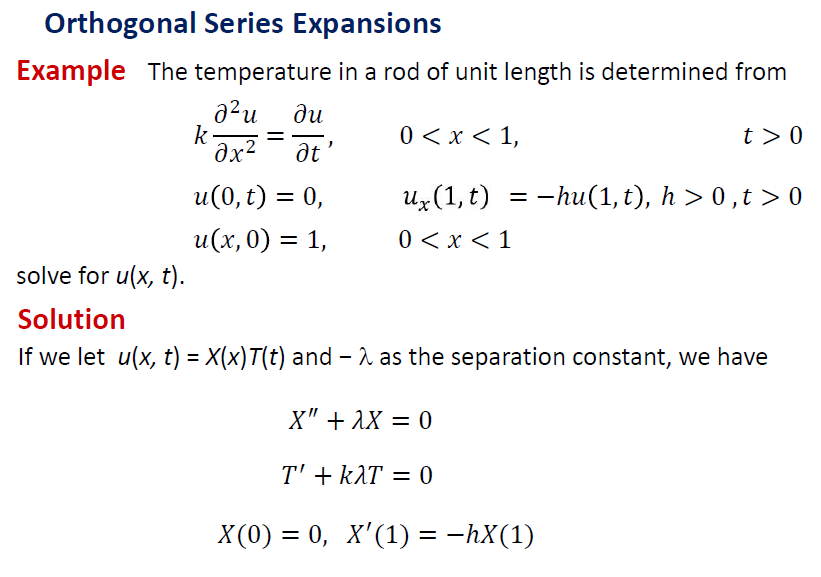

**Separation part**

clear
clf
clc
syms x t u(x,t) L D h
assume([L D],"positive")
HeatEq = diff(u,t) == D*diff(u,x,2)

$$HeatEq(x, t) = \frac{\partial }{\partial t}u\left(x,t\right)=\text{D}\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)$$

BC0 = u(0,t) == 0;
syms  T(t) X(x)
Sepvar = subs(HeatEq,u(x,t),X(x)*T(t));
BCx0 = subs(BC0,u(0,t),X(0))

$$BCx0 = X\left(0\right)=0$$

Sepvar = Sepvar/(D*X(x)*T(t));
var = children(Sepvar);
syms lambda
assume(lambda,"positive")
eqT = var(1) == -lambda^2

$$eqT = \frac{\frac{\partial }{\partial t}T\left(t\right)}{\text{D}\,T\left(t\right)}=-\lambda^{2}$$

eqX = var(2) == -lambda^2

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

T(t,lambda) = dsolve(eqT)

$$T(t, lambda) = C_{1}\,{\mathrm{e}}^{-\text{D}\,\lambda^{2}\,t}$$

X(x,lambda) = dsolve(eqX,BCx0);
constantX = setdiff(symvar(X(x,lambda)),sym(['C',x,lambda]));
X(x,lambda) = subs(-X(x,lambda),constantX,sym('C2'))

$$X(x, lambda) = C_{2}\,\sin\left(\lambda \,x\right)$$

DxL(x,lambda) = diff(X,x);
sln = DxL(L,lambda) == -h*X(L,lambda)

$$sln = C_{2}\,\lambda \,\cos\left(L\,\lambda \right)=-C_{2}\,h\,\sin\left(L\,\lambda \right)$$

var = children(sln);
syms b_n ustruct(x,t,n);
expT(t,n) = subs(T(t,lambda),[lambda,sym('C1')],[lambda,sym('1')]);
sinX(x,n) = subs(X(x,lambda),[lambda,sym('C2')],[lambda,b_n]);
ustruct(x,t,n) = collect(sinX(x,n)*expT(t,n),["sin" "exp"])

$$ustruct(x, t, n) = b_{n}\,{\mathrm{e}}^{-\text{D}\,\lambda^{2}\,t}\,\sin\left(\lambda \,x\right)$$

lambda = var(2)*lambda/var(1)

$$lambda = -\frac{h\,\sin\left(L\,\lambda \right)}{\cos\left(L\,\lambda \right)}$$

**Plot "tan x = -x" and display "x"**

clf
L = 4

L = 4

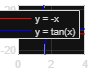

fplot(@(x) -x,[0,L],'r');
grid on, hold on
fplot(@tan,[0,L],'b')
legend('y = -x','y = tan(x)')

x = linspace(0,L);
fun = @(x) tan(x)+x;
f = fun(x);
I = find(sign(f(2:end))-sign(f(1:end-1)));
r = zeros([1 length(I)]);
for n = 1:length(I)
    r(n) = vpa(fzero(fun, x([I(n),I(n)+1])));
end

**Orthogonal Series Expansions**

syms x t n b(n) phi(x)
assume(n,"integer")
phi(x) = 1;
ft0 = subs(ustruct(x,0,n),sym(["b_n" "L"]),[1 L])

$$ft0 = \sin\left(\lambda \,x\right)$$

bnum(n) = simplify(int(phi(X)*ft0,x,[0 L]));
bden(n) = simplify(int(ft0^2,x,[0 L]));
[Num,Den] = numden(bnum);
Den = subs(Den,sym("lambda"),lambda);
bnum(n) = subs(Num/Den,sym("L"),L);
[Num,Den] = numden(bden);
Den = subs(Den,sym("lambda"),lambda);
bden(n) = subs(Num/Den,sym("L"),L);
D = 1

D = 1

solution = subs(ustruct,"D",D)

$$solution(x, t, n) = b_{n}\,{\mathrm{e}}^{-\lambda^{2}\,t}\,\sin\left(\lambda \,x\right)$$

b(n) = simplify(bnum/bden)

$$b(n) = \frac{8\,{\sin\left(2\,\lambda \right)}^{2}}{8\,\lambda -\sin\left(8\,\lambda \right)}$$

heatstructEmb(x,t,n) = subs(ustruct,sym(["b_n" "L" "D"]),[b L D])

$$heatstructEmb(x, t, n) = \frac{8\,{\sin\left(2\,\lambda \right)}^{2}\,{\mathrm{e}}^{-\lambda^{2}\,t}\,\sin\left(\lambda \,x\right)}{8\,\lambda -\sin\left(8\,\lambda \right)}$$

Emb = 0;
for i = 2:length(I)
    Emb = Emb+subs(heatstructEmb(x,t,i),sym("lambda"),r(i));
end
heatSolN(x,t) = Emb

$$heatSolN(x, t) = -\frac{8\,{\sin\left(\frac{2284178260934781}{562949953421312}\right)}^{2}\,{\mathrm{e}}^{-\frac{5217470327727040476995935517961\,t}{1267650600228229401496703205376}}\,\sin\left(\frac{2284178260934781\,x}{1125899906842624}\right)}{\sin\left(\frac{2284178260934781}{140737488355328}\right)-\frac{2284178260934781}{140737488355328}}$$

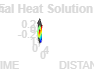

figure
colormap jet
fsurf(heatSolN,[0 L 0 L/4],"EdgeColor","interp")
title("Final Heat Solution")
xlabel('DISTANCE','FontSize',8);
ylabel('TIME','FontSize',8);
zlabel('TEMPERATURE','FontSize',8);

**Heat profile at different times**

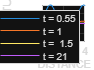

clf
tm = [0.5 1 1.5 2];
for i = 1:length(tm)
    sn  = matlabFunction(heatSolN(x,tm(i)));
    fplot(sn,[0 L])
    grid on, hold on
end
xlabel('DISTANCE','FontSize',8);
ylabel('TEMPERATURE','FontSize',8)
legend('t = 0.55','t = 1','t =  1.5','t = 21','Location','southeast')

**Heat profile at various times**

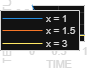

clf
dst = [1 1.5 3];
for i = 1:length(dst)
    sn  = matlabFunction(heatSolN(dst(i),t));
    fplot(sn,[0 1])
    grid on, hold on
end
xlabel('TIME','FontSize',8);
ylabel('TEMPERATURE','FontSize',8)
legend('x = 1','x = 1.5','x = 3','Location','northeast')

page 40

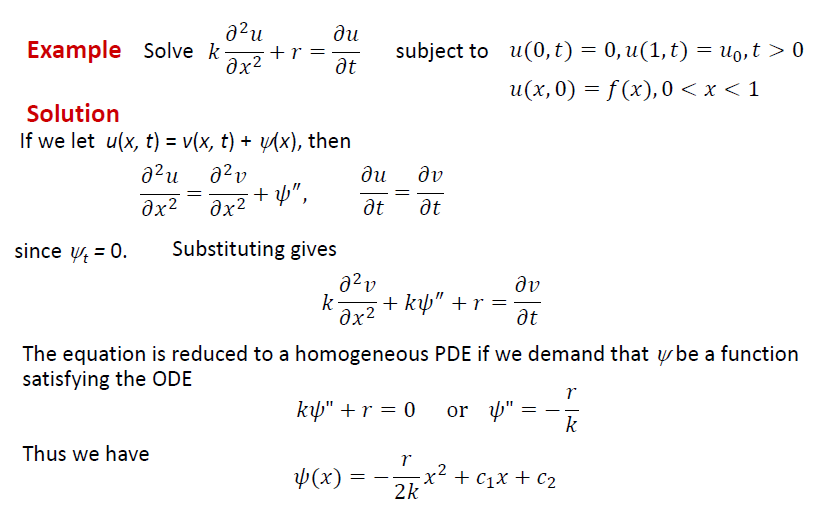

clear
syms x t k r u(x,t) v(x,t) psi(x) f(x) n A(x) pi A_n
syms u_0
heatequa=k*diff(u,x,2)+r==diff(u,t)

$$heatequa(x, t) = k\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)+r=\frac{\partial }{\partial t}u\left(x,t\right)$$

assume(t,"positive")
bc0=u(0,t)==0;
bc1=u(1,t)==u_0;
U=v(x,t)+psi(x)

$$U = \psi \left(x\right)+v\left(x,t\right)$$

sepvar=subs(heatequa,u(x,t),U)

$$sepvar(x, t) = r+k\,\left(\frac{\partial^{2}}{\partial x^{2}}\psi \left(x\right)+\frac{\partial^{2}}{\partial x^{2}}v\left(x,t\right)\right)=\frac{\partial }{\partial t}v\left(x,t\right)$$

var(x)=subs(sepvar,v(x,t),'V') %demand that psi be a function satisfying the ODE

$$var(x) = k\,\frac{\partial^{2}}{\partial x^{2}}\psi \left(x\right)+r=0$$

eq=dsolve(var)

$$eq = C_{2}+C_{1}\,x-\frac{r\,x^{2}}{2\,k}$$

bcv0=subs(bc0,u(0,t),v(0,t)+psi(0));
bcv1=subs(bc1,u(1,t),v(1,t)+psi(1));
consPsi0=subs(bcv0,v(0,t),0)

$$consPsi0 = \psi \left(0\right)=0$$

consPsi1=subs(bcv1,v(1,t),0) %given v(0,t)&v(1,t)=0

$$consPsi1 = \psi \left(1\right)=u_{0}$$

eq=subs(eq,[sym('C1'),sym('C2')],[(r/(2*k))+u_0,0])

$$eq = x\,\left(u_{0}+\frac{r}{2\,k}\right)-\frac{r\,x^{2}}{2\,k}$$

vx0 = f(x)- eq

$$vx0 = f\left(x\right)-x\,\left(u_{0}+\frac{r}{2\,k}\right)+\frac{r\,x^{2}}{2\,k}$$

v(x,t)= symsum(A(n)*exp(-k*n^2*pi^2*t)*sin(n*pi*x),n,1,Inf)

$$v(x, t) = \sum_{n=1}^{\infty }\sin\left(n\,\pi \,x\right)\,{\mathrm{e}}^{-k\,n^{2}\,\pi^{2}\,t}\,A\left(n\right)$$

A_n = 2*int(v(x,0)*sin(n*pi*x),x,[0 1])

$$A\_n = 2\,\int_{0}^{1}\sin\left(n\,\pi \,x\right)\,\left(\sum_{n=1}^{\infty }\sin\left(n\,\pi \,x\right)\,A\left(n\right)\right)\mathrm{d}x$$

u(x,t) = eq + v(x,t)

$$u(x, t) = x\,\left(u_{0}+\frac{r}{2\,k}\right)+\left(\sum_{n=1}^{\infty }\sin\left(n\,\pi \,x\right)\,{\mathrm{e}}^{-k\,n^{2}\,\pi^{2}\,t}\,A\left(n\right)\right)-\frac{r\,x^{2}}{2\,k}$$

page 47

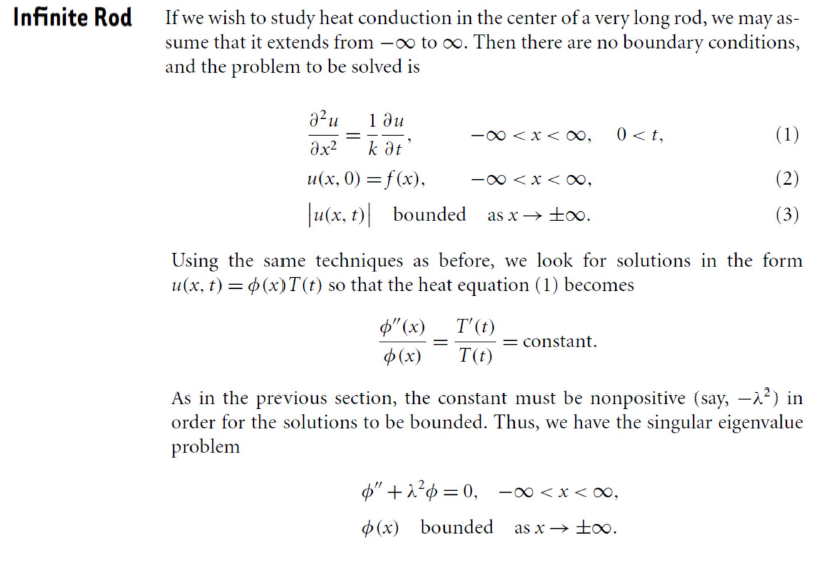

**Separation part**

clear
clc
syms x t u(x,t) L D h f(x)
assume([L D],"positive")
HeatEq = diff(u,t) == D*diff(u,x,2)

$$HeatEq(x, t) = \frac{\partial }{\partial t}u\left(x,t\right)=\text{D}\,\frac{\partial^{2}}{\partial x^{2}}u\left(x,t\right)$$

BC0 = u(x,0) == f(x);
syms T(t) X(x)
SepVar = subs(HeatEq,u(x,t),X(x)*T(t));
BCx0 = subs(BC0,u(x,0),X(0))

$$BCx0 = X\left(0\right)=f\left(x\right)$$

SepVar = SepVar/(D*X(x)*T(t));
var = children(SepVar);
syms lambda
assume(lambda,"positive")
eqT = var(1) == -lambda^2

$$eqT = \frac{\frac{\partial }{\partial t}T\left(t\right)}{\text{D}\,T\left(t\right)}=-\lambda^{2}$$

eqX = var(2) == -lambda^2

$$eqX = \frac{\frac{\partial^{2}}{\partial x^{2}}X\left(x\right)}{X\left(x\right)}=-\lambda^{2}$$

T(t,lambda) = dsolve(eqT)

$$T(t, lambda) = C_{1}\,{\mathrm{e}}^{-\text{D}\,\lambda^{2}\,t}$$

X(x,lambda) = dsolve(eqX)

$$X(x, lambda) = C_{1}\,\cos\left(\lambda \,x\right)-C_{2}\,\sin\left(\lambda \,x\right)$$

constantX = setdiff(symvar(X(x,lambda)),sym(['C',x,lambda]))

$$constantX = \left(\begin{array}{cc} C_{1} & C_{2} \end{array}\right)$$

%X(x,lambda) = subs(-X(x,lambda),constantX(2))
syms A B 
expT(t,lambda) = subs(T(t,lambda),[lambda,sym('C1')],[lambda,sym('1')]);
sinX(x,lambda) = subs(X(x,lambda),[lambda,sym('C1'),sym('C2')],[lambda,A,-B]);
ustruct(x,t) = collect(sinX(x,lambda)*expT(t,lambda),["sin" "exp"]);
int(ustruct,lambda,0,inf)%combime the solution expT, sinX in the form of an integral to obtain

$$ans(x, t) = \int_{0}^{\infty }\left(B\,{\mathrm{e}}^{-\text{D}\,\lambda^{2}\,t}\,\sin\left(\lambda \,x\right)+\left(A\,\cos\left(\lambda \,x\right)\right)\,{\mathrm{e}}^{-\text{D}\,\lambda^{2}\,t}\right)\mathrm{d}\lambda$$

**Fourier integral part**

syms x t b(lambda) phi(x) 


fx0 = subs(ustruct,[A,B,t],[1,0,0]);
fx1 = subs(ustruct,[A,B,t],[0,1,0]);
a(lambda) = 1/sym('pi')*int(fx0*f(x),x,-inf,inf)

$$a(lambda) = \frac{\int_{-\infty }^{\infty }\cos\left(\lambda \,x\right)\,f\left(x\right)\mathrm{d}x}{\pi }$$

b(lambda) = 1/sym('pi')*int(fx1*f(x),x,-inf,inf)

$$b(lambda) = \frac{\int_{-\infty }^{\infty }\sin\left(\lambda \,x\right)\,f\left(x\right)\mathrm{d}x}{\pi }$$


%heatstructEmb(x,t,lambda) = subs(ustruct,sym(["A" "B" "D"]),[a b D])